# Calibrate sovereign risk function

## Generalized logistic function


$$q_t = f(z_t) =  \underline q + \left(\overline q - \underline q\right) \left[ \frac{1}{1 + \exp-\frac{z_t-\mu}{\sigma} } \right]^{\exp\nu}$$


where


$$z_t \equiv \frac{(1+rx_{t+1}) \, \mathit{nfa}_t}{\mathit{ngdp}_{t+1}}$$


is the expected value of net government assets to GDP ratio and the function parameters have the following meaning

- $\underline z$ the lower bound

- $\overline z$ the upper bound

- $\mu$ the location parameter (left or right shift)

- $\sigma$ the scale parameter (dispersion)

- $\nu$ the shape parameter (asymmetry)

## Clear workspace


close all
clear

figure( );


## Vector of NFA to GDP ratios


z = linspace(-1.50, 0.50, 500);


## Choose parameters and plot the function

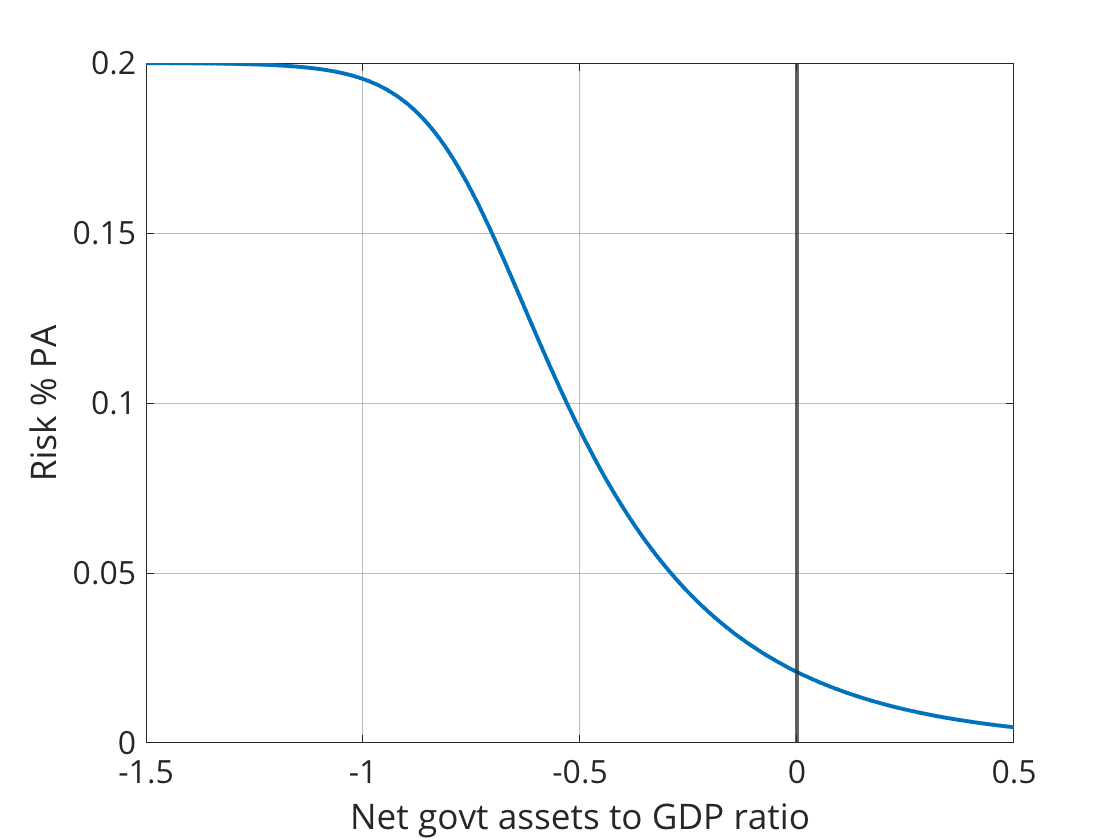

% Location parameter
mu = -0.75 ;

% Scale parameter (dispersion)
sigma = 0.1;

% Shape parameter (symmetry)
nu = -1.2;

% Lower bound
low = 0;

% Upper bound
high = 0.2;

%% Plot CDF 

plot(z, glogc0(-z, -mu, sigma, nu, low, high));
set(gca( ), "xLim", [min(z), max(z)], "yLim", [0, high]);
xline(0, "lineWidth", 2);
xlabel("Net govt assets to GDP ratio");
ylabel("Risk % PA");